# Aula 15 - Observador de Estados

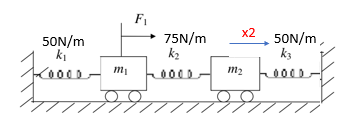

## Controlar a posição x2 utilizando-se a força F1

### a) Obter a resposta a um degrau de 100N em F1

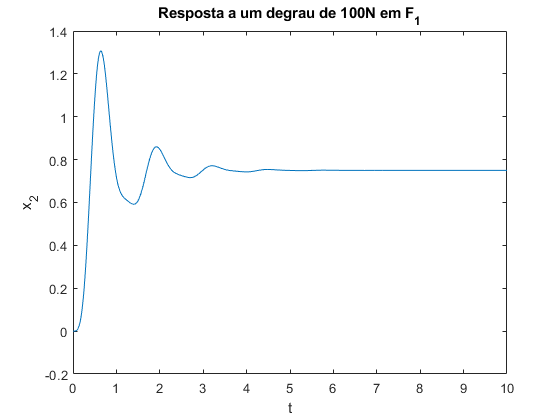

clear
m1 = 2;
m2 = 2;
k1 = 50;
k2 = 75;
k3 = 50;
b1 = 5;
b2 = 5;
A=[0,1,0,0; -k1/m1-k2/m2,-b1/m1,k2/m2,0; 0,0,0,1; k2/m2,0,-k3/m2-k2/m2,-b2/m2];
B=[0;1/m1;0;0];
C=[0,0,1,0];
D=0;
sys_ma=ss(A,B,C,D);
nt=1000;
t=linspace(0,10,nt);
r=zeros(1,nt);
r(1,:)=100;
[y,t,x] = lsim(sys_ma,r,t);
plot(t,y(:,1));
xlabel("t")
ylabel("x_2")
title("Resposta a um degrau de 100N em F_1")

lsiminfo(y,t)

ans = struct with fields:
    SettlingTime: 3.3458
             Min: -5.7903e-24
         MinTime: 0
             Max: 1.3069
         MaxTime: 0.6406


### b) Implemente um regulador com polos em malha fechada próximos a -11 (todos reais)

% Considerando apenas F1 e X2
p=[-10;-11;-12;-13];
K=place(A,B,p)

K = 	1.0e+03 *

    1.1145    0.0820   -1.0756    0.0938


Kr=1;
sys_mf=ss(A-B*K,B*Kr,C,0)

sys_mf =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2  -619.8   -43.5   575.3  -46.88
   x3       0       0       0       1
   x4    37.5       0   -62.5    -2.5
 
  B = 
        u1
   x1    0
   x2  0.5
   x3    0
   x4    0
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



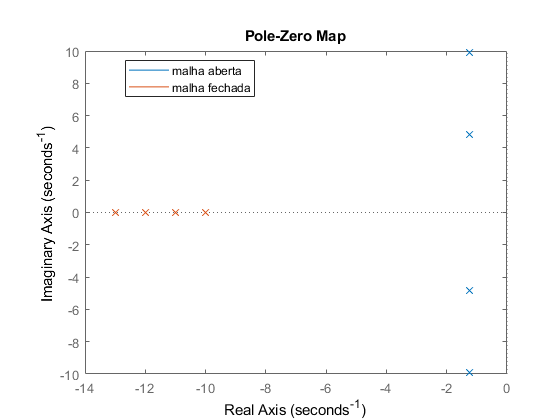

pzmap(sys_ma)
hold on
pzmap(sys_mf)
legend('malha aberta','malha fechada','Location',"best")
hold off

### c) Simule a resposta ao se iniciar com x1(0)=1  ; x2(0)=-1  com e sem controle

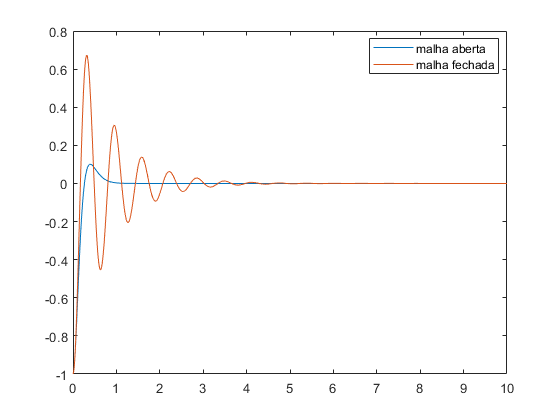

t=linspace(0,10,nt);
x0=[1,0,-1,0];
[yma,t,xma]=initial(sys_ma,x0,t);
[ymf,t,xmf]=initial(sys_mf,x0,t);
plot([t,t],[ymf,yma])
legend('malha aberta','malha fechada','Location',"best")

### d) Implemente um seguidor de referência e simule uma referência a degrau unitário

Para o sistema o regulador anteriormente calculado virar um seguidor de referência, falta apenas calcular o ganho $K_r$.

Kr=1/dcgain(sys_mf)

Kr = 915.2000

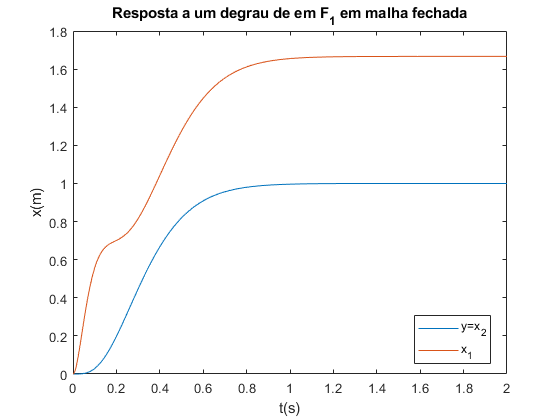

sys_mf=ss(A-B*K,B*Kr,C-D*K,D*Kr);
nt=1000;
t=linspace(0,2,nt);
r=zeros(1,nt);
r(1,:)=1;
[y,t,x] = lsim(sys_mf,r,t);
plot(t,x(:,3));
hold on
plot(t,x(:,1));
hold off
xlabel("t(s)")
ylabel("x(m)")
title("Resposta a um degrau de em F_1 em malha fechada")
legend('y=x_2','x_1',"Location","best")

### e) Implemente um observador de estados com polos 5 vezes mais rápidos que o sitema em malha fechada


$$x_e=\left\{\begin{array}{c}        x \\     \hat  x \\    \end{array}\right\}$$



$$\dot x_e = \left(\begin{array}{c c}  A & -BK \\  LC & A-BK-LC    \end{array}\right)x_e+ \left\{\begin{array}{c}  BK_r \\  BK_r   \end{array}\right\}r=A_{obs}x_e+B_{obs}r$$



$$y_e=\left\{\begin{array}{c}        y \\     \hat  y \\    \end{array}\right\}= \left(\begin{array}{c c}  C & 0 \\  0 & C    \end{array}\right)+Dr= C_{obs}x_e+Dr$$


p_obs=5*p;
L=place(A',C',p_obs)'

L = 	1.0e+05 *

    0.1843
    2.0805
    0.0022
    0.1852


Kr=1;
A_obs=[A,-B*K;L*C,A-B*K-L*C];
B_obs=[B*Kr;B*Kr];
C_obs=[C,zeros(size(C));zeros(size(C)),C];
D_obs=0;
obsys=ss(A_obs,B_obs,C_obs,D_obs);
Kr=1/dcgain(obsys(1))

Kr = 915.2000

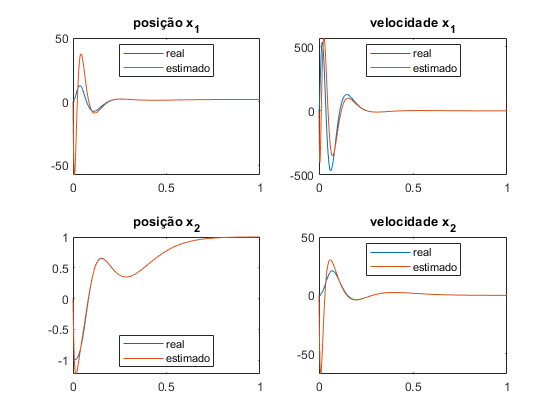

A_obs=[A,-B*K;L*C,A-B*K-L*C];
B_obs=[B*Kr;B*Kr];
C_obs=[C,zeros(size(C));zeros(size(C)),C];
D_obs=0;
obsys=ss(A_obs,B_obs,C_obs,D_obs);
x0=[1,0,-1,0,0,0,0,0];
n=1000;
t = linspace(0,1,n);
R = zeros(n,1);
R(:) = 1;
[y,t,x] = lsim(obsys,R,t,x0);
subplot(2,2,1);
plot([t,t],[x(:,1),x(:,5)])
legend('real','estimado',"Location","best")
title('posição x_1')
subplot(2,2,2);
plot([t,t],[x(:,2),x(:,6)])
legend('real','estimado',"Location","best")
title('velocidade x_1')
subplot(2,2,3);
plot([t,t],[x(:,3),x(:,7)])
legend('real','estimado',"Location","best")
title('posição x_2')
subplot(2,2,4);
plot([t,t],[x(:,4),x(:,8)])
legend('real','estimado',"Location","best")
title('velocidade x_2')